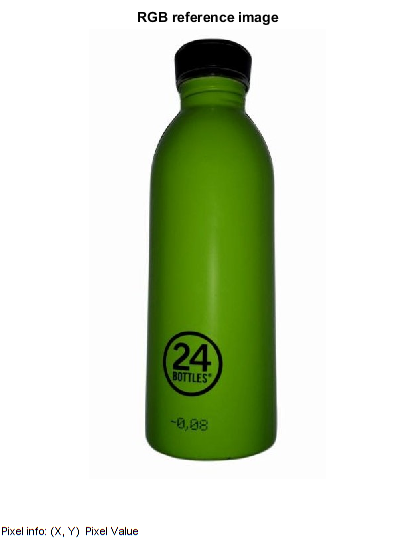

%Luca Sugamosto, matricola 0324613
%Procedura 30: Visione artificiale su una borraccia

clc
clear
close all

%Caricamento dell'immagine per lo studio
refImage = imread("Borraccia.jpg");
%Permette di visualizzare l'immagine a schermo
imshow(refImage);
%Per mezzo della funzione seguente è possibile osservare i valori RGB dei
%pixel dell'immagine raffigurata
impixelinfo;    

title('RGB reference image');

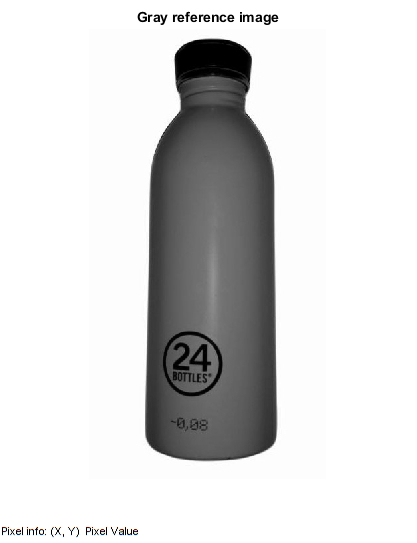

%Passaggio dall'immagine a colori (in cui ad ogni pixel è associato un
%vettore RGB) ad un'immagine  in scala di grigi (in cui ad ogni pixel è
%associato una costante tra 0 e 255).
refImageGray = rgb2gray(refImage);

figure(2);
%Permette di visualizzare l'immagine a schermo
imshow(refImageGray);
%Per mezzo della funzione seguente è possibile osservare il valore [0,255]
%dei pixel dell'immagine raffigurata
impixelinfo;

title('Gray reference image');

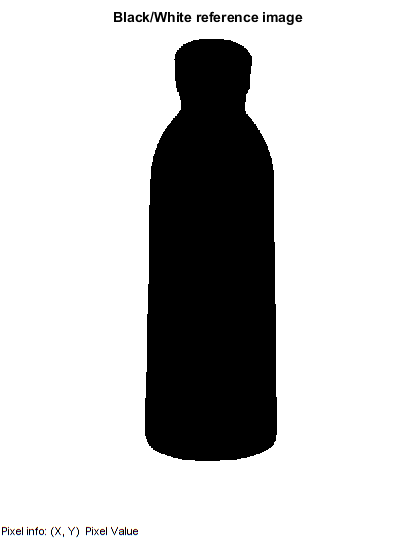

%Passaggio dall'immagine in scala di grigi ad un'immagine in bianco e nero
%(in cui ad ogni pixel è associato una costante pari a 0 o 1).
%Si utilizza un valore di soglia associato alla luminanza che permette di
%associare il pixel al valore 0 (nero) o 1 (bianco).
refImageBW = imbinarize(refImageGray,0.65);

figure(3);
%Permette di visualizzare l'immagine a schermo
imshow(refImageBW);
%per mezzo della funzione seguente è possibile osservare il valore binario
%[0,1] dei pixel dell'immagine raffigurata
impixelinfo;

title('Black/White reference image');

%Calcolo delle dimensioni dell'immagine così da scandire pixel per pixel e
%calcolare l'area dell'oggetto.
larghezzaImage = width(refImage);       %larghezza dell'immagine in input
altezzaImage = length(refImage);        %altezza dell'immagine in input

%Calcolo l'area dell'immagine andando a contare tutti i pixel interessanti
%con valore binario 0 (pixel nero).
area = 0;

for i = 1:1:larghezzaImage
    for j = 1:1:altezzaImage
        value = impixel(refImageBW,i,j);
        if value(3) == 0
            area = area+1;
        end
    end
end

%Stampare a schermo l'area dell'oggetto nell'immagine
fprintf('Area della borraccia vale [pixel]:');

Area della borraccia vale [pixel]:

disp(area);

      107306



fprintf('\n');

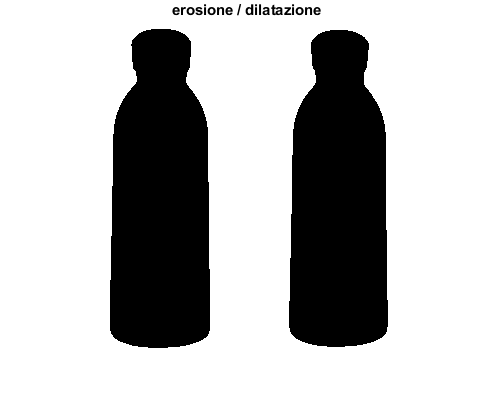

%Per calcolare il perimetro dell'oggetto nell'immagine si utilizzano le
%funzioni di "erosione" e "dilatazione" applicate sull'immagine in bianco e
%nero. Infine si fa la differenza e si contano i pixel rimasti che
%definiscono il perimetro.

%La seguente inizializzazione è essenziale per erosioni/dilatazioni poichè
%definisce la struttura di valutazione dei pixel, nel nostro caso è un
%quadrato.
se = strel('square',3);

%Operazione di EROSIONE
erodeImage = imerode(refImageBW,se);
%Operazione di DILATAZIONE
dilateImage = imdilate(refImageBW,se);

figure(4);
%Si mettono a confronto le due immagini calcolate
imshowpair(erodeImage,dilateImage,'montage');
title('erosione / dilatazione');

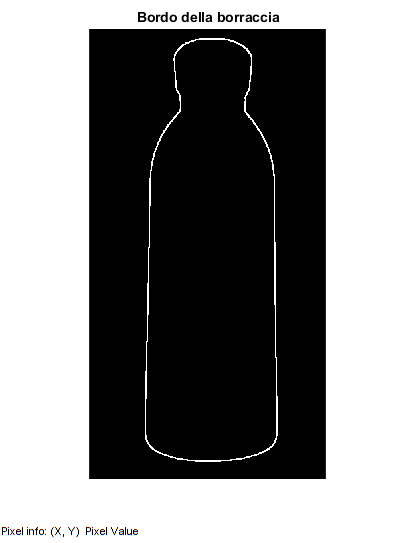


%Eseguo la differenza pixel per pixel tra le foto calcolate per far tornare
%il bordo della borraccia ed in seguito calcolarne il perimentro
finalImage = dilateImage-erodeImage;

figure(5);
imshow(finalImage);
impixelinfo;
title('Bordo della borraccia');

%Calcolo perimetro (conteggio pixel bianchi)
perimetro = 0;

for i = 1:1:larghezzaImage
    for j = 1:1:altezzaImage
        value = impixel(finalImage,i,j);
        if value(3) == 1
            perimetro = perimetro+1;
        end
    end
end

%Stampare a schermo il perimetro dell'oggetto nell'immagine
fprintf('Perimetro della borraccia vale [pixel]:');

Perimetro della borraccia vale [pixel]:

disp(perimetro);

        3407



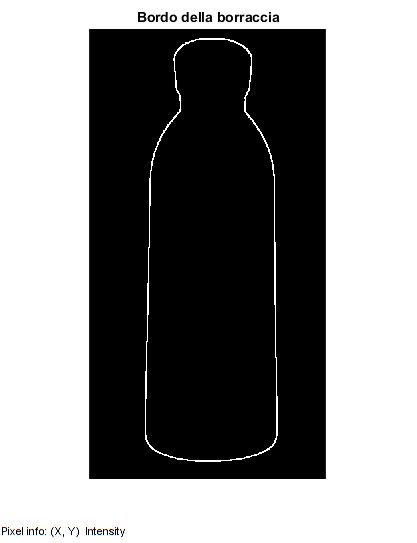

%Calcolo dell'orientamento dell'oggetto rispetto all'asse orizzontale x
imageBW = imcomplement(refImageBW);

figure(6);
imshow(imageBW);

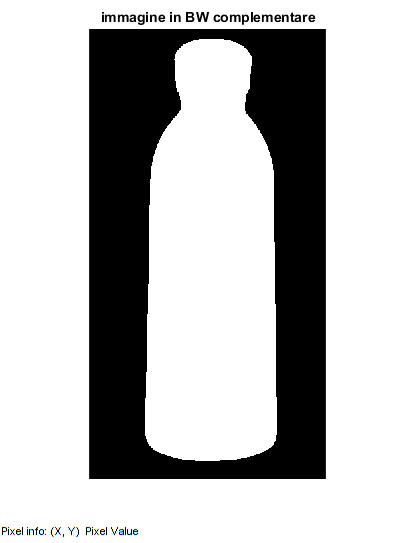

impixelinfo;
title('immagine in BW complementare');


%La funzione 'regionprops' con l'opzione 'orientation' calcola l'angolo tra
%l'asse x e l'asse maggiore dell'ellisse creatosi intorno all'oggetto da
%anlizzare. Il valore è in gradi e compreso tra -90° e 90°.
angolo = regionprops(imageBW,'Orientation');
fprintf("Orientamento della borraccia [gradi]:");

Orientamento della borraccia [gradi]:

disp(angolo);

    Orientation: 89.7040

